***Nodos de chevychev: ***La idea es buscar los nodos que ***mejor ***aproximan a un polinomio de interpolacion. Los ceros del polinomio de Chevychev son los que mejor aproximan.

**Ejemplo**

Dada la funcion f(x)= ln(x^2+3)*exp(-3*x) halle polinomio de grado menor igual a 5 que **mejor aproxime** la funcion y halle una cota para el error.

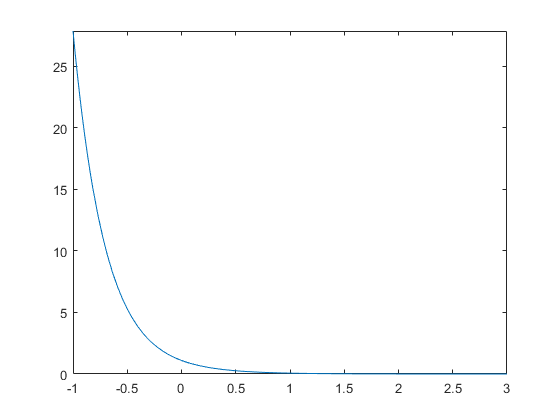

f = @(x) log(x.^2+3).*exp(-3*x);
fplot(f,[-1 3]) % Grafica de la funcion a modificar.

Se usa la rutina para calcular los nodos de chevychev

[C, X, Y] = cheby (f, 5, -1, 3) % Se coloca la funcion, grado del polinomio 

C =     4.4071   -8.0956    6.3090   -4.2171    2.4068   -1.0517


X =     2.9319    2.4142    1.5176    0.4824   -0.4142   -0.9319


Y =     0.0004    0.0016    0.0176    0.2760    3.9991   22.1481


% a interpolar e intervalo donde se va a trabajar.

%cheby(funcion, grado, a,b)

% C no tiene los coeficientes del polinomio interpolante. No sirve pa Na...
% X son los nodos TRASLADADOS, YA EN EL INTERVALO PEDIDO

Si se grafican los nodos calculados en la curva, podremos ver graficamente los nodos de chevychev.

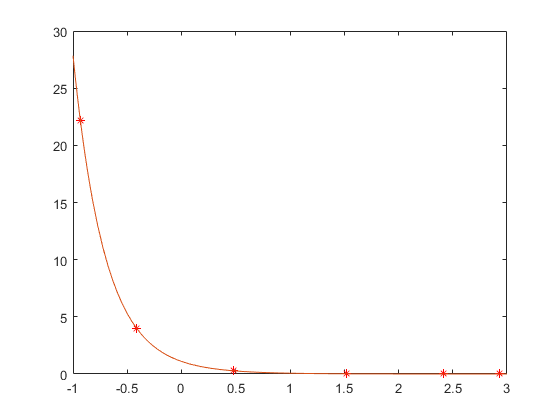

plot(X,Y,"*r") % Los ptos rojos minimizan el error
hold on
fplot(f,[-1 3]) % funcion
hold off

[C, D] = newpoly (X, Y) % Calculo del polinomio de newton con nodos finded

C =    -0.5259    3.8327   -9.5515    9.2576   -2.9138    0.4058


D =     0.0004         0         0         0         0         0
    0.0016   -0.0023         0         0         0         0
    0.0176   -0.0179    0.0110         0         0         0
    0.2760   -0.2496    0.1200   -0.0445         0         0
    3.9991   -4.1526    2.0203   -0.6719    0.1875         0
   22.1481  -35.0612   21.8557   -8.0978    2.2193   -0.5259


Graficando el polinomio de newton y la funcion se tiene que:

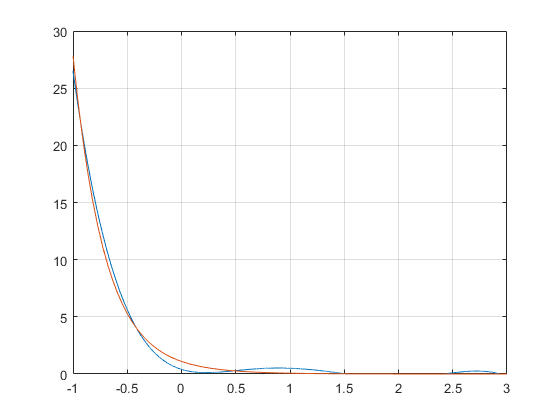

hold off

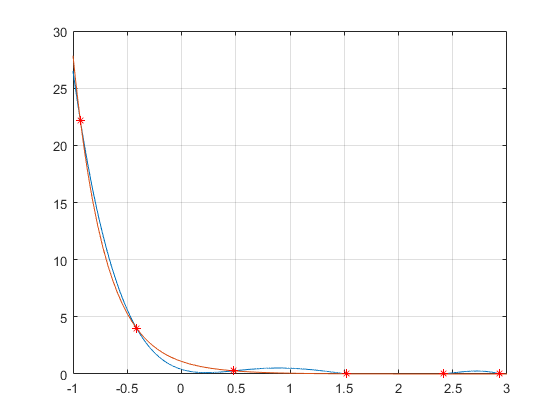

xx = linspace(-1,3,10000); % Grafique esta nube de puntos en el intervalo trabajado
yy = polyval(C,xx); %Evalue la nube de puntos y guardelos en yy
plot(xx,yy) %Grafica de los puntos 
hold on
fplot(f)
plot(X,Y,"*r") 
axis([-1 3 0 30])
grid on

Claramente la grafica se asemeja bastante a la funcion.